# Ephys Behavior: Compare Performance

clear; close all; clc;
animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
animals = length(animalID);

main_dir = get_data_root();
meta_table = readtable(fullfile(main_dir,'Metadata.xlsx'),"Sheet",'Data ID');

colors = {'#284B5E','#BC554C'};
days = 6;
trials = 25;

% Define output variables
genotype_idx = nan(1,animals);
errors_animals = cell(days,animals);                    % trials x total:rm:wm
entry_count_animals = cell(days,animals);               % zones x trials
inter_trial_animals = cell(days,animals);               % normal errors: R1-R3
inter_trial_rm_animals = cell(days,animals);            % rm errors: R1-R3
inter_trial_wm_animals = cell(days,animals);            % wm errors: R1-R3

save_path = fullfile(main_dir,'CompiledData');

## Compile data

for a = 1:length(animalID)

    identity = [meta_table.animal_id,meta_table.experiment_type];
    date = cell2mat(meta_table.date);

    exp = find((identity(:,1) == animalID(a) & identity(:,2) == 2)+(identity(:,1)== animalID(a) & identity(:,2) == 3));
    [session,~] = size(date(exp,:));
    validity = meta_table.validity_behavior(exp);
    d = date(exp,:);



    for s = 1:session
        if validity(s) == 1

        d = date(exp(s),:);
        else

            continue
        end

        session_num = 'A';
        animal_ID = num2str(animalID(a));

        % load variables
        path = char(fullfile(main_dir,animal_ID,d,session_num,'data/Processed'));
        load(fullfile(path, 'postprocessed.mat'));
        load(fullfile(path, 'behavior.mat'));

        index = find(strcmp(meta_table.date, d) == 1 & meta_table.animal_id == str2double(animal_ID));
        g = meta_table.genotype(index); % 1 = control, 2 = exp
        genotype_idx(1,a) = g; 

        errors_animals{s,a} = error;
        entry_count_animals{s,a} = entry_dist_count;
        inter_trial_animals{s,a} = inter_trial_errors;
        inter_trial_rm_animals{s,a} = inter_trial_errors_rm;
        inter_trial_wm_animals{s,a} = inter_trial_errors_wm;

    end
end

% Save the compiled data
save(fullfile(save_path,'CompiledBehavior.mat'),"genotype_idx","errors_animals","entry_count_animals","inter_trial_animals","inter_trial_rm_animals","inter_trial_wm_animals");


## Compare performance

load(fullfile(save_path,'CompiledBehavior.mat'));
contr = genotype_idx == 1; 
exp = genotype_idx == 2; 

initialize_box = nan(max(sum(exp),sum(contr)),2);
for i = 1:days
    
    performance = nan(trials,animals);
    for a = 1:animals
        if isempty(errors_animals{i,a})
            continue
        else
            performance(:,a) = errors_animals{i,a}(:,1);
        end
    end

    perf_avr = average_matrix(performance,animals,5);

    figure('Visible','off')
    p = plot(perf_avr(:,contr),'LineWidth',2);
    [p(1).Color] = char(colors{1});
    [p(2).Color] = char(colors{1});
    hold on
    e = plot(perf_avr(:,exp),'LineWidth',2);
    [e(1).Color] = char(colors{2});
    [e(2).Color] = char(colors{2});
    xlim([1 5]);
    xticks(1:1:5);
    xlabel('Trial Block');
    ylabel('# Errors');
    title(sprintf('Day %d',i));

    no_error = sum(performance == 0);

    initialize_box(1:sum(contr),1) = no_error(contr)';
    initialize_box(1:sum(exp),2) = no_error(exp)';

    figure('Visible','off')
    boxplot(initialize_box)
    hold on
    scatter(1,initialize_box(:,1),'filled','jitter','on','jitterAmount',0.08)
    scatter(2,initialize_box(:,2),'filled','jitter','on','jitterAmount',0.08)
    ylabel(sprintf('High Performance Day %d',i));

    %%% Average trial performance accross days %%%

    performance_days(i,:) = mean(performance);
    no_error_days(i,:) = no_error;    
end




## Compare genotypes

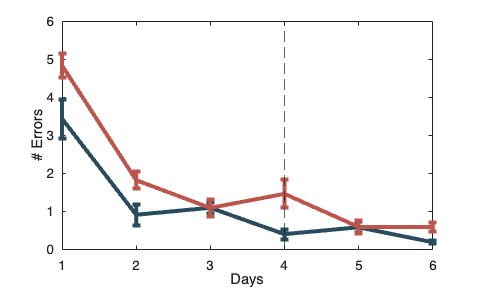

figure
errorbar(mean(performance_days(:,contr)','omitnan'), SE(performance_days(:,contr)'), 'LineWidth', 3, 'Color', colors{1}); 
hold on
errorbar(mean(performance_days(:,exp)','omitnan'), SE(performance_days(:,exp)'), 'LineWidth', 3, 'Color', colors{2});
xlim([1 6]);
xticks(1:1:6);
xline(4,'--');
ylabel('# Errors');
xlabel('Days');

## Statistics

% Build long-format table
group_labels = {'Control', 'Experimental'};
all_data = [];
contr_idx = [1,2,3,4];
exp_idx = [5,6,7,8];
TB1 = 1:3;
TB2 = 4:6;
TB = {TB1,TB2};
for t = 1:length(TB)
    for day = TB{1,t}
        % Loop through control animals
        for idx = contr_idx
            dat = errors_animals{day, idx};
            if ~isempty(dat) && ~isnan(dat(1))
                temp = table();
                temp.Day = categorical(day);
                temp.Group = categorical("Control");
                temp.Subject = categorical("C" + idx);  % e.g., C1, C2...
                temp.Response = mean(dat(:,1));  % Take mean if multiple values
                all_data = [all_data; temp];
            end
        end
    
        % Loop through experimental animals
        for idx = exp_idx 
            dat = errors_animals{day, idx};
            if ~isempty(dat) && ~isnan(dat(1))
                temp = table();
                temp.Day = categorical(day);
                temp.Group = categorical("Experimental");
                temp.Subject = categorical("E" + idx);  % e.g., E5, E6...
                temp.Response = mean(dat(:,1));
                all_data = [all_data; temp];
            end
        end
    end
    
    % Fit linear mixed-effects model
    lme = fitlme(all_data, 'Response ~ Group*Day + (1|Subject)');
    
    % Display ANOVA table
    anova_tbl = anova(lme)
   
end

anova_tbl =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        108.69    1      17     8.3786e-09
    {'Day'        }         29.28    2      17     3.1138e-06
    {'Group'      }        9.0011    1      17      0.0080517
    {'Day:Group'  }        3.4534    2      17        0.05513


anova_tbl =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        153.46    1      33     5.8886e-14
    {'Day'        }        28.491    5      33     4.4632e-11
    {'Group'      }        12.709    1      33      0.0011349
    {'Day:Group'  }        3.1132    5      33       0.020701
